# **Sankey**

## Overview

The `Sankey` chart comprises nodes and links. The links represent flow from one node to another, and the size of the link is proportional to the flow rate.

Clicking on a link provides more detailed information about the source and target nodes as well as the flow rate. Clicking on a node will highlight all incoming and outgoing links.

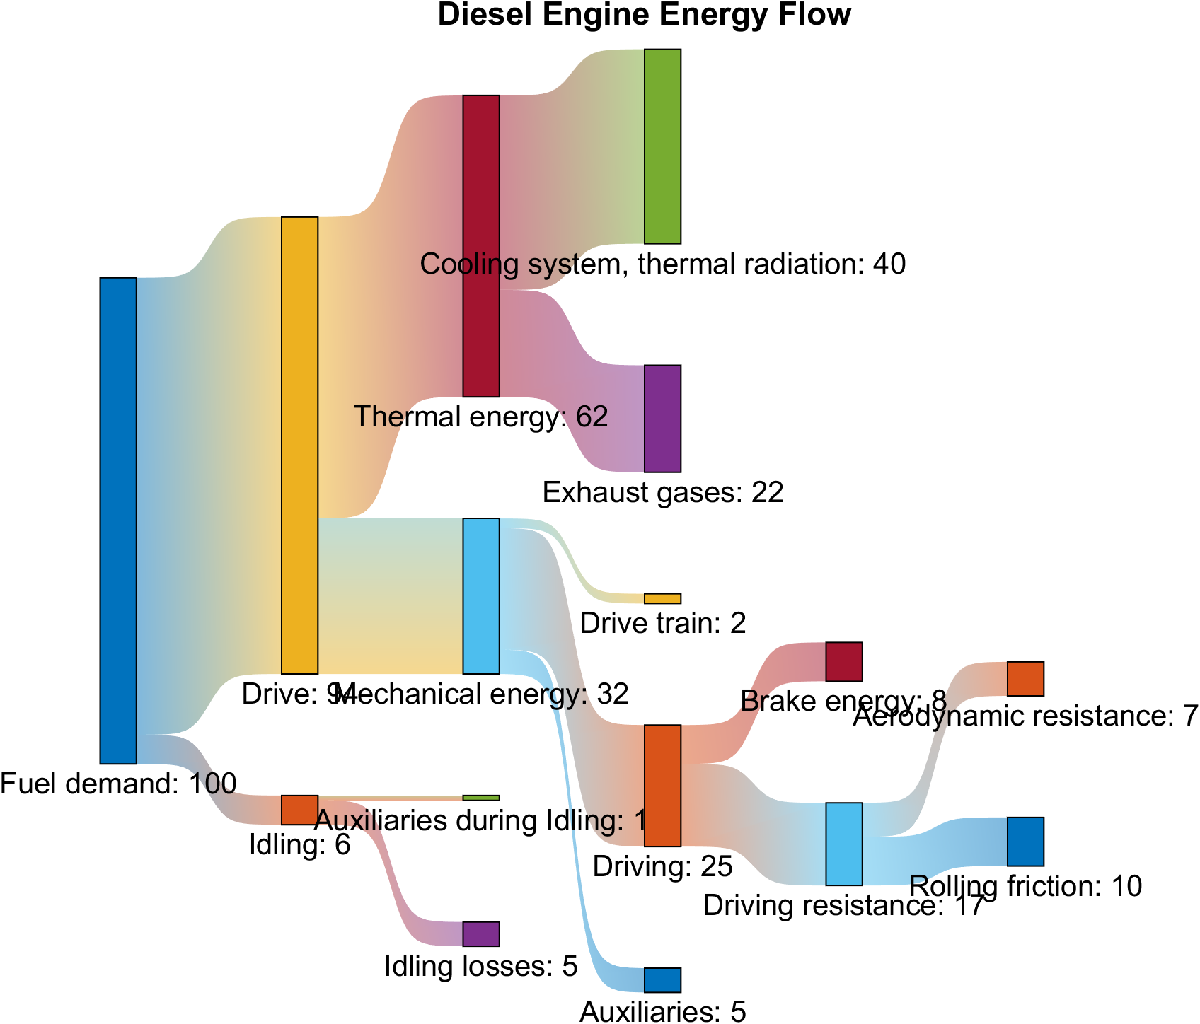

## Resources

[Open](matlab: edit(fullfile(catalogRoot, "+example", "Sankey.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "Sankey.m"))) the source code for the `Sankey` chart.

Documentation for:

- [`digraph`](matlab: doc("digraph")): Graph with directed links

- [`patch`](matlab: doc("patch")): Plot one or more filled polygonal regions

## Define the chart data.

The chart data is specified using a directed graph. The links represent the flow between two nodes, using the weight to specify the flow rate.

sourceNodes = [1, 1, 2, 2, 3, 4, 5];
sinkNodes = [3, 4, 4, 5, 6, 6, 7];
flowRates = [4, 2, 3, 1, 4, 5, 1];
nodeLabels = ["A", "B", "C", "D", "E", "F", "G"];
DG = digraph( sourceNodes, sinkNodes, flowRates, nodeLabels );
disp( DG )

  digraph with properties:

    Edges: [7×2 table]
    Nodes: [7×1 table]



## Create a figure for the chart.

f = exampleFigure( "Name", "Sankey Example", "Color", "w" );

## Create the chart.

Next, create the chart object, specifying the `Parent` and `GraphData` properties.

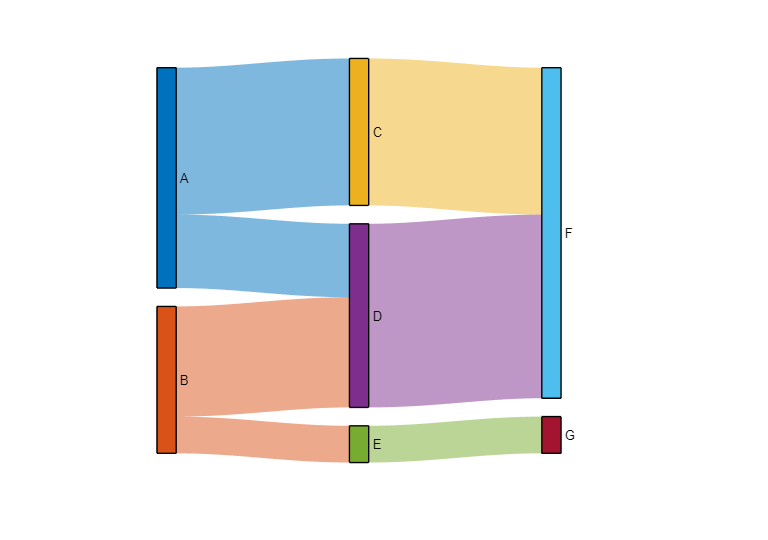

S = chart.Sankey( "Parent", f, "GraphData", DG );

## Change link properties.

### Color

The links' color can be specified as a single color, or can be connected to the nodes via the `"source"`, `"target"` and `"gradient"` options.

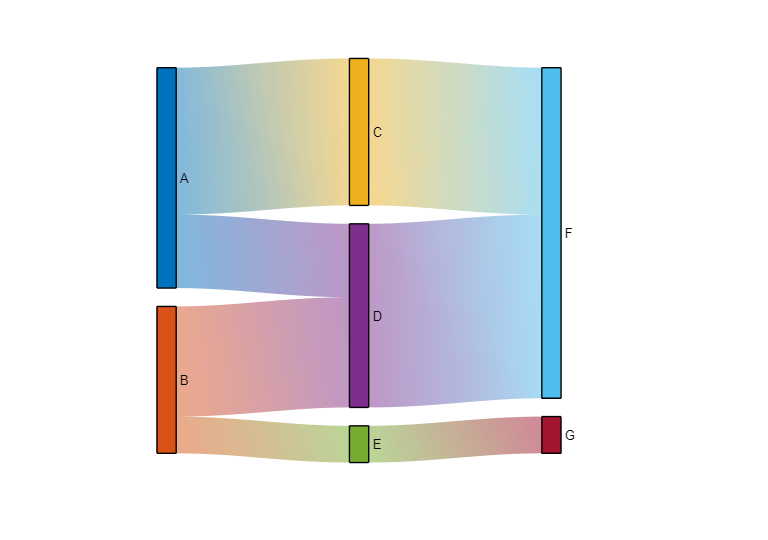

S.LinkColor = "gradient";

### Type

We can adjust the shape of the chart's links. Options starting with "v" will have a constant vertical cross section while others have a constant perpendicular cross section.

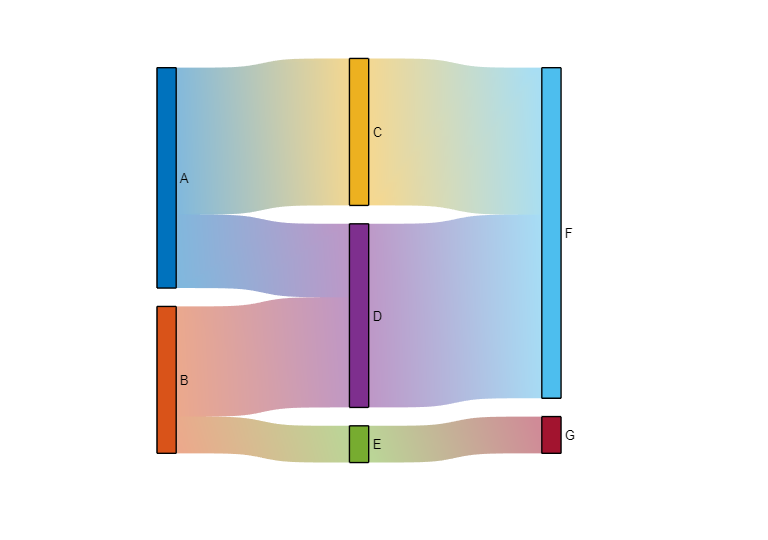

S.LinkType = "vtanh";

## Change node properties.

### Color

We can modify the nodes' color using RGB triples.

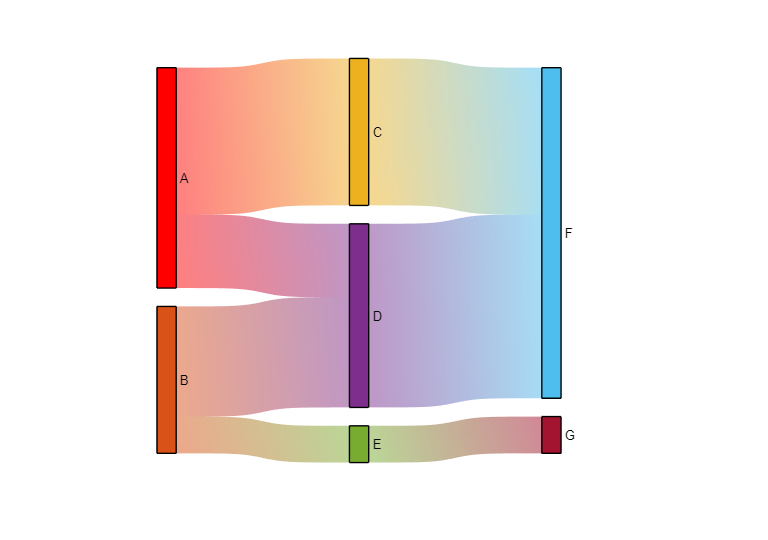

S.NodeColor(1,:) = [1, 0, 0];

### Vertical spacing

We can modify the vertical spacing as a percentage of the nodes' total height.

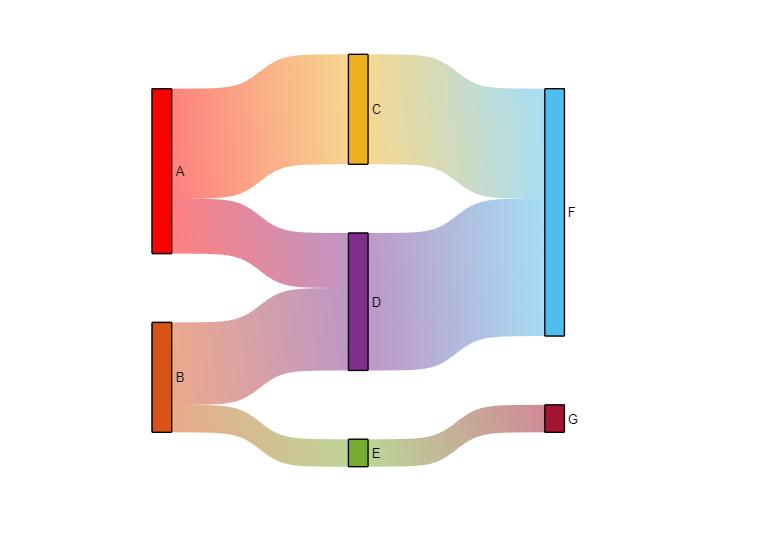

S.NodePadRatio = 0.25;

### Width

Modify the nodes' width.

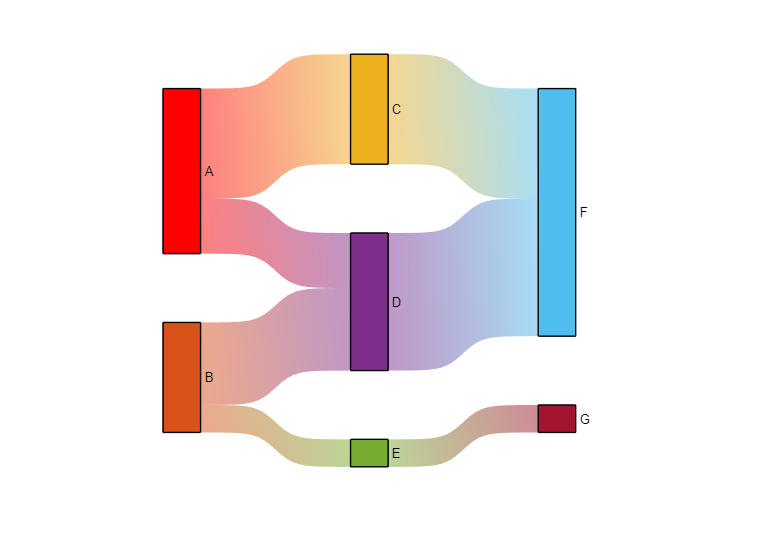

S.NodeWidth = 0.2;

### Position

Reposition the nodes by specifying their $x$ and $y$ coordinates.

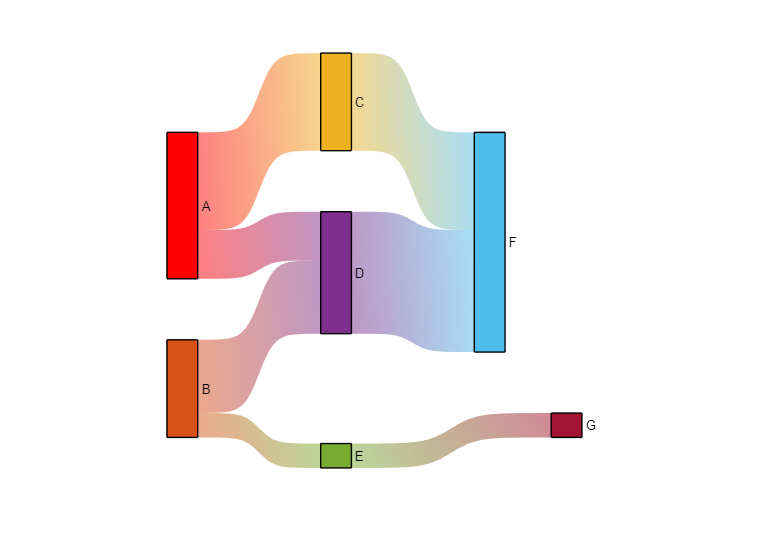

S.XNodeData(end) = 3.5;
S.YNodeData([3,4]) = S.YNodeData([3,4]) + 2;

### Label position

Modify the label position relative to the node.

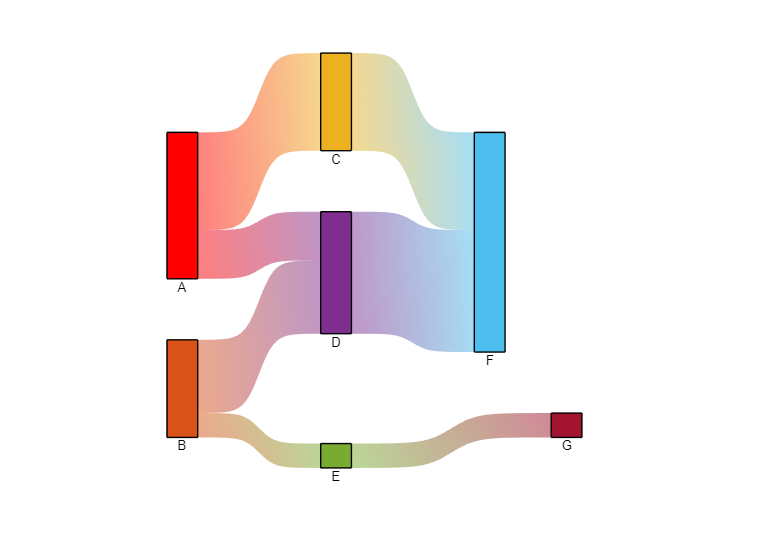

S.LabelAlignment = "bottom";

### Label content

Modify the label content to display the total flow or not.

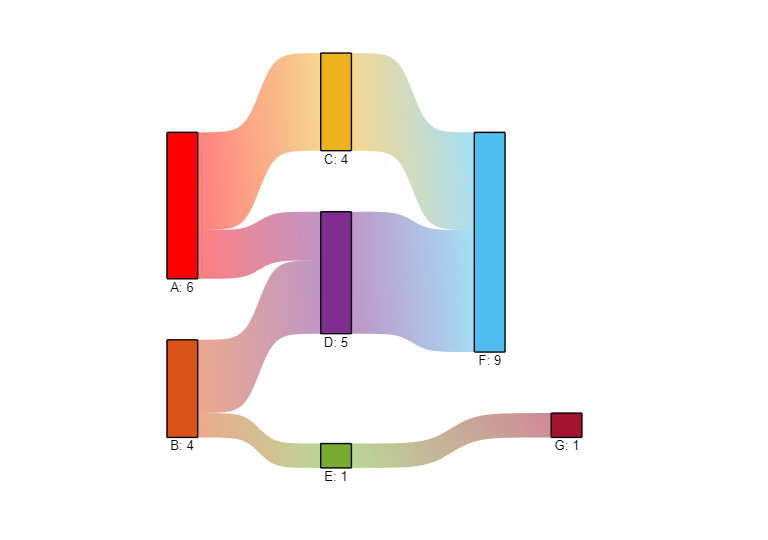

S.LabelIncludeTotal = "on";

For nodes that have different incoming and outgoing flows, the label will show the difference in the form: $\left\lbrace \textrm{in}\right\rbrace \longrightarrow \left\lbrace \textrm{out}\right\rbrace$

## Modify the chart data.

Let's display a more complex graph representing an energy flow diagram.

Load sample chart data, obtained from figure 1 in:

- Hay, B. & Hameury, Jacques & Scoarnec, V & Davée, G & Grelard, M. (2011). *The Contribution of the Metrology of Thermophysical Properties of Materials in Automotive Design.*

load( fullfile( catalogRoot(), "data", "Graph.mat" ) )
disp( linkData )

                             EndNodes                              Weight
    ___________________________________________________________    ______

    "Fuel demand"           "Idling"                                  6  
    "Fuel demand"           "Drive"                                  94  
    "Idling"                "Idling losses"                           5  
    "Idling"                "Auxiliaries during Idling"               1  
    "Drive"                 "Mechanical energy"                      32  
    "Drive"                 "Thermal energy"                         62  
    "Mechanical energy"     "Auxiliaries"                             5  
    "Mechanical energy"     "Driving"                                25  
    "Mechanical energy"     "Drive train"                             2  
    "Thermal energy"        "Exhaust gases"                          22  
    "Thermal energy"        "Cooling system

Create a graph from the link table.

DG = digraph( linkData );

Modify the data in the chart.

S.GraphData = DG;

Adjust the node position.

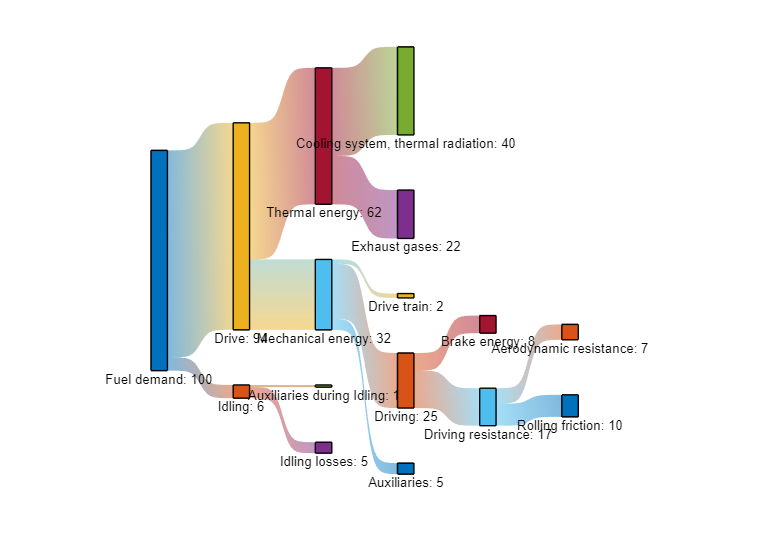

S.YNodeData(13:end) = S.YNodeData(13:end) - 50;

## Annotate the chart.

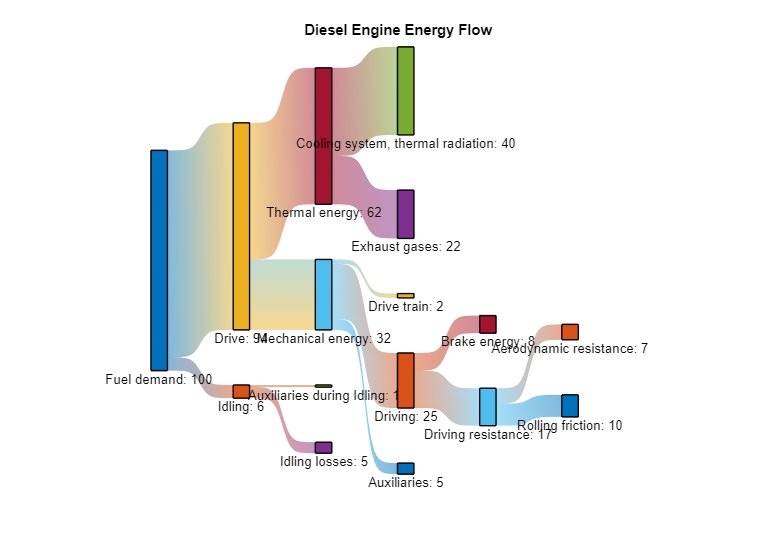

title( S, "Diesel Engine Energy Flow" )

*Copyright 2021-2022 The MathWorks, Inc.*